# **No Chain PCE  --  Multiple point-Bayesian inference**

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - COMPUTATIONAL MODEL

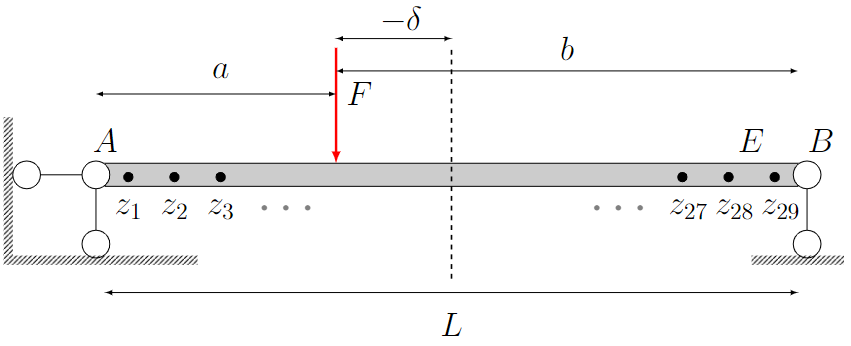

        b_b = 0.15; % beam width  (m)

        b_h = 0.3; % beam height (m)

        a = 13% distance from the point A (m)

        b = 17 % distance from the point B (m)

        L = 30; % beam length (m)

        F = 43000±10000;% Concentrated force (N)

        E = 30e9;%elastic modulus

        delta = -2; loading position

**Computational model:**

$a = \frac{L}{2}- \delta$;$b = \frac{L}{2}+ \delta$


$$\mathcal{M}(\vec{\theta}) = \frac{F b  z  [(L^2 - b^2) - z^2]}{6LEI} \ \ \   \ \ \ \ \ \ \ z \le a$$
 


$$\mathcal{M}(\vec{\theta})  =  \frac{F b  [\frac{L}{b} (z - a)^3 + (L^2 - b^2)]}{6LEI} \ \ \ \ z> a
$$



$$\vec{\theta} = [E,\delta,z];\vec{z} = [z_1,z_2,...,z_{28},z_{29}];$$


 $E $ is elastic modulus; $\delta$ is the loading postion

$\vec{z} $is the different measurement points along the beam;

$\mathcal{M}$ is the FE model; $Y_i$ is the measurement data; $N$ is the number of experiment expNum.

Create a MODEL from the function file:

% %LHS sampling 
% 
% % mean of LHS sampling for Gaussian distribution (E and delta)
% mu_LHS = 43000;
% 
% % sigma and Covariance martrix of LHS sampling for Gaussian distribution (E and delta)
% sigma_LHS = [10000].^2;
% CovarianceMatrix_LHS = diag(sigma_LHS);

% Uniform sampling 
N = 50;
p = 1;
F_lhs = lhsdesign(N, p, 'criterion', 'none');
lower_limit_F = -9e4;
upper_limit_F = 9e4;
F_Uniform_sample = lower_limit_F + F_lhs * (upper_limit_F - lower_limit_F);
size(F_Uniform_sample)

ans =     50     1



F = F_Uniform_sample;
size(F)

ans =     50     1


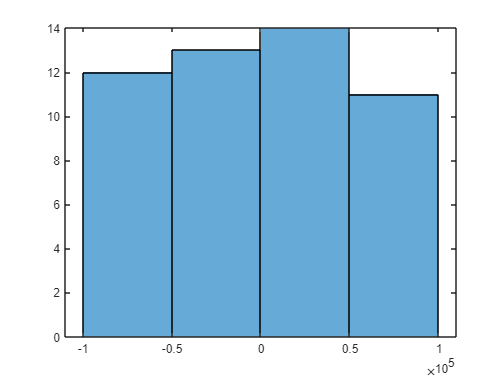

%plot uniform sampling
figure
histogram(F)

%FE realizaiton 
FE_deflection = Deflection(F);
size(FE_deflection)

ans =     50    29


FE_realization = [F_Uniform_sample,FE_deflection];
size(FE_realization)

ans =     50    30


## 3 - PROBABILISTIC INPUT MODEL


$$F \sim \mathcal{u}(43000,10000)$$


% Young's modulus
InputOpts.Marginals(1).Type = 'Uniform';
minF = min(FE_realization(:,1));
size(minF)

ans =      1     1


maxF = max(FE_realization(:,1));
size(maxF)

ans =      1     1


InputOpts.Marginals(1).Parameters  = [minF maxF];



myInput = uq_createInput(InputOpts);

## 4 - POLYNOMIAL CHAOS EXPANSION (PCE) METAMODELS $\tilde{\mathcal{M}}(r)$

Calculate the polynomial chaos expansion (PCE) coefficients.

Select PCE as the metamodeling tool in UQLab:

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';

Select the sparse-favouring least-square minimization LARS for the 

PCE coefficients calculation strategy:

metaopts.Method = 'LARS';

Select the PCE options and create the PCE model:

metaopts.Degree = 1:20;

Experimental design

X = FE_realization(:,1);
Y = FE_realization(:,2:end);
metaopts.ExpDesign.X = X;
metaopts.ExpDesign.Y = Y;

Calculation

myPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 1 and qNorm 1.00 for output variable 1
Final LOO error estimate: 3.696673e-32
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 1 and qNorm 1.00 for output variable 2
Final LOO error estimate: 1.039962e-31
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 1 and qNorm 1.00 for output variable 3
Final LOO error estimate: 3.601541e-32
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 1 and qNorm 1.00 for output variable 4
Fin

Print a summary of the resulting PCE metamodel:

uq_print(myPCE, [1:29])

%------------ Polynomial chaos output ------------%
   Number of input variables:    1
   Maximal degree:               1
   q-norm:                       1.00
   Size of full basis:           2
   Size of sparse basis:         2
   Full model evaluations:       50
   Leave-one-out error:          3.4162450e-32
   Modified leave-one-out error: 3.6966731e-32
   Mean value:                  -0.0016
   Standard deviation:           0.2871
   Coef. of variation:         17491.826%
%--------------------------------------------------%

%------------ Polynomial chaos output ------------%
   Number of input variables:    1
   Maximal degree:               1
   q-norm:                       1.00
   Size of full basis:           2
   Size of sparse basis:         2
   Full model evaluations:       50
   Leave-one-out error:          9.6107082e-32
   Modified leave-one-out error: 1.0399619e-31
   Mean value:                  -0.0033
   Standard deviation:           0.5713
   Coef. of variation:  

Export the PCE strucuture

save myPCE

## 5 - Yval vs YPCE

Create a validation sample of size  from the input model:

Xval =  FE_realization(:,1);
size(Xval)

ans =     50     1


Evaluate the full model response at the validation sample points:

Yval =  FE_realization(:,2:end);
size(Yval)

ans =     50    29


Responses for PCE 

YPCE = uq_evalModel(myPCE,Xval);
size(YPCE)

ans =     50    29


True vs predicted plot

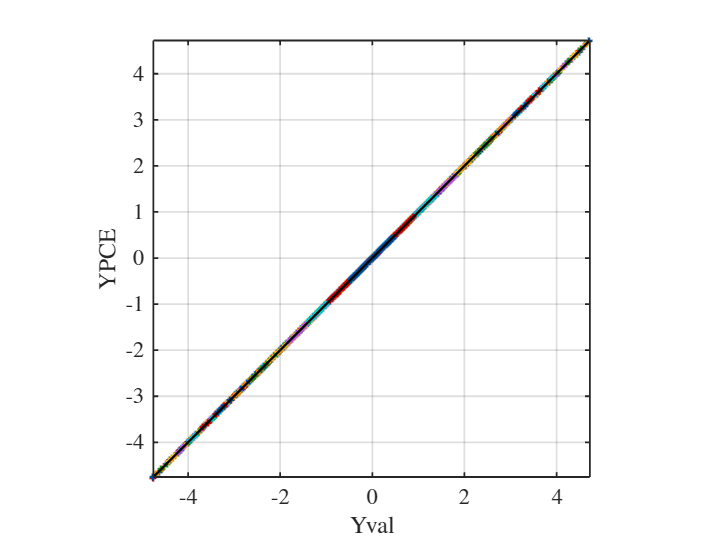

close all;
uq_figure
uq_plot(Yval, YPCE, '+')
hold on
uq_plot([min(Yval,[],'all') max(Yval,[],'all')], [min(Yval,[],'all') max(Yval,[],'all')], 'k')
hold off
axis equal
axis([min(Yval,[],'all') max(Yval,[],'all') min(Yval,[],'all') max(Yval,[],'all')])
xlabel('Yval');
ylabel('YPCE');
box on;

show the covariance matrix of y_FE-output

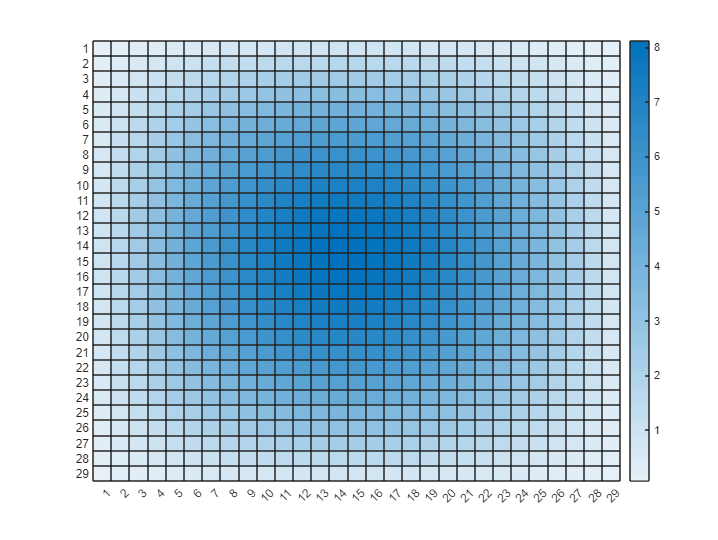

Output_FE_COV = cov(FE_deflection);
heatmap(Output_FE_COV)

show the covariance matrix of PCE-output

N_PCE = size(FE_deflection,2);
max_len = 15;
PCE_Coeffi_Sum = [];
for i = 1:N_PCE
    PCE_i_Coeffi = myPCE.PCE(i).Coefficients;
    PCE_Coeffi = [PCE_i_Coeffi;zeros(max_len - length(PCE_i_Coeffi),1)];
    PCE_Coeffi_Sum = [PCE_Coeffi_Sum PCE_Coeffi];
end

Calculate the variance of PCE analytically

PCE_Cov = [];
for i = 1:N_PCE
    for j = 1:N_PCE       
        PCE_Cov(i,j) = dot(PCE_Coeffi_Sum(2:15,i),PCE_Coeffi_Sum(2:15,j));
    end
end


show the covariance matrix of PCE

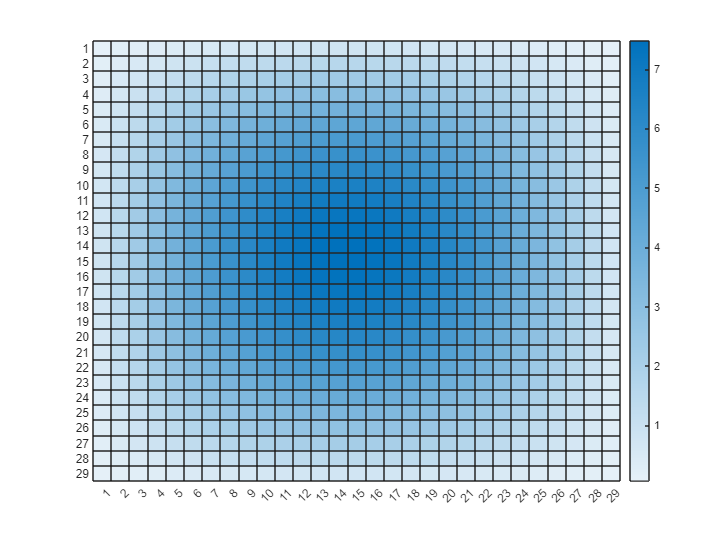

heatmap(PCE_Cov)

## 6 - Define the priors for F and discrepancy $\sigma$

## **Note: priors for F are different from input models above**

By default, UQlab assumes an independent and identically distributed discrepancy

$\varepsilon \sim \mathcal{N}(0,\mu_{y}^2)$, with $\mu_{y} = \frac{1}{N}\sum_{i = 1}^{N}y_i$

#### synthetic ground truth with 3% noise 

F = 30000N; noise = 5%

Measurement = GroundTruth(30e9,-2,30000,1,0.10);
size(Measurement)

ans =      1    29


 priors

%Priors on E , delta and sigma
PriorOpts.Marginals(1).Name = 'F';               % Loading F
PriorOpts.Marginals(1).Type = 'Uniform';
PriorOpts.Marginals(1).Parameters = [-43000 43000];   % (N)
PriorOpts.Marginals(1).Bounds = [-9e5 9e5];




% PriorOpts.Marginals(2).Name = 'sigma2'; % variance
% PriorOpts.Marginals(2).Type = 'Uniform';
% sigma2 = mean(Measurement(:,:),"all");
% PriorOpts.Marginals(2).Parameters = [0 sigma2^2];


myPriorDist = uq_createInput(PriorOpts);

SigmaOpts.Marginals(1).Name = 'Sigma2';
SigmaOpts.Marginals(1).Type = 'Uniform';
sigma2 = mean(Measurement(:,:),"all");
SigmaOpts.Marginals(1).Parameters = [0 sigma2.^2];

mySigmaDist = uq_createInput(SigmaOpts);
DiscrepancyOptsUnknownDisc.Type = 'Gaussian';
DiscrepancyOptsUnknownDisc.Prior = mySigmaDist;

## 7 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$\ell\mathcal{L} ({\vec{\theta}},{\epsilon} \mid {Y}) = \prod_{i=1}^{N}\frac{1}{(2\pi)^{{3}/2}\det({\Sigma}(\epsilon))^{1/2}}\exp\left(-\frac{1}{2}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)^{{T}} {\Sigma}(\epsilon)^{-1}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)\right)$$



myData.y = Measurement;
size(myData.y)

ans =      1    29


myData.Name = 'Measurement on 29 points along the beam';

Loglikelihood still follows the Gaussian discrepancy criteria

myLogLikeli = @(params,y) myLogLikeli2(params,y);

## 8 - Solver options


Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 500;
Solver.MCMC.NChains = 50;
Solver.MCMC.Proposal.PriorScale = 1e-3;

## 9 - Bayesian inference


Starting AIES...

|#                             |   1.80%|#                             |   3.60%|##                            |   6.00%|##                            |   7.80%|###                           |   9.60%|####                          |  12.00%|####                          |  13.80%|#####                         |  15.60%|#####                         |  18.00%|######                        |  19.80%|######                        |  21.60%|#######                       |  24.00%|########                      |  25.80%|########                      |  27.60%|#########                     |  30.00%|##########                    |  31.80%|##########                    |  33.60%|###########                   |  36.00%|###########                   |  37.80%|############                  |  39.60%|#############                 |  42.00%|#############                 |  43.80%|##############                |  45.60%|##############                |  48.00%|###############     

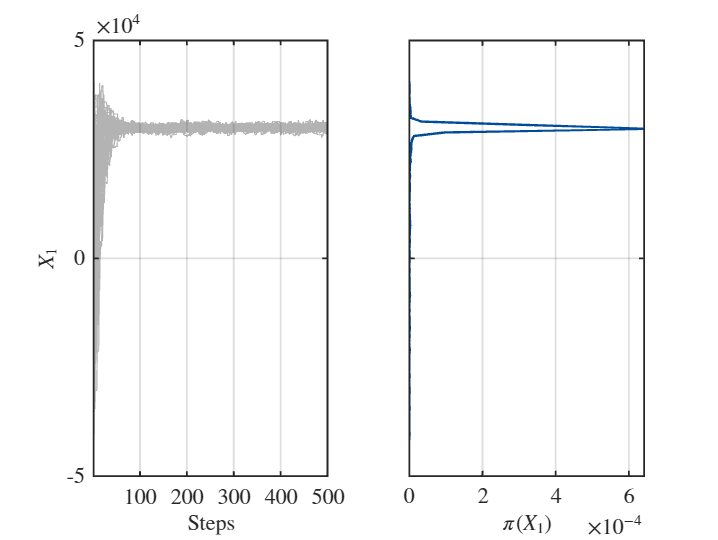

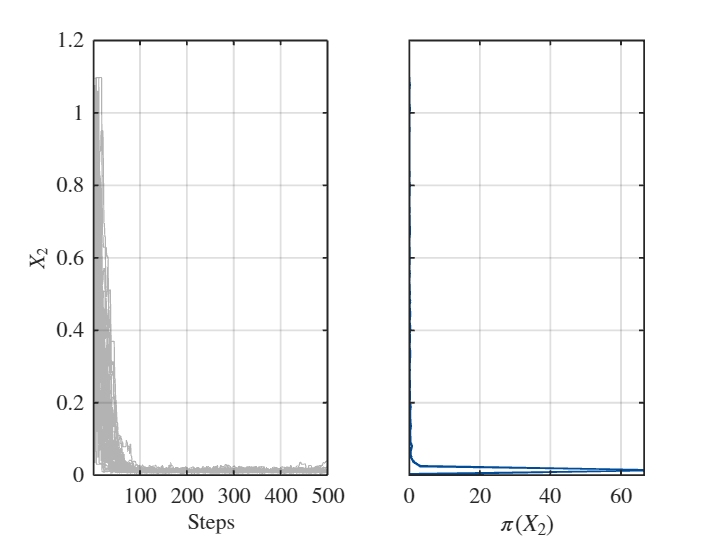


Finished AIES!


BayesOpts.Discrepancy = DiscrepancyOptsUnknownDisc;
BayesOpts.ForwardModel.Model = myPCE;
BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);

## 10 - Post-processing

Burn in 70%; badchain criteria $\delta > 10m$; confidence interval 90%; Point estimate - mean


badChainsIndex = squeeze(BayesAnalysis.Results.Sample(end,1,:) <-20000);

uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','mean','percentiles',[0.05,0.95],'burnin',0.7,'badChains',badChainsIndex);




uq_print(BayesAnalysis);

%----------------------- Inversion output -----------------------%
   Number of calibrated model parameters:         1
   Number of non-calibrated model parameters:     0

   Number of calibrated discrepancy parameters:   1

%------------------- Data and Discrepancy
%  Data-/Discrepancy group 1:
   Number of independent observations:            1

   Discrepancy:
      Type:                                       Gaussian
      Discrepancy family:                         Scalar
      Discrepancy parameters known:               No

   Associated outputs:
      Model 1: 
         Output dimensions:                       1
                                                  to
                                                  29


%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:01:24
   Number of sample points:                       2.50e+04

%------

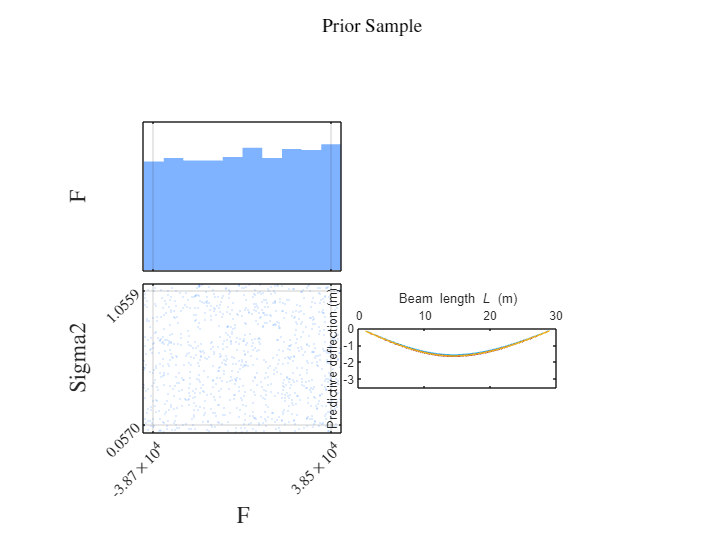

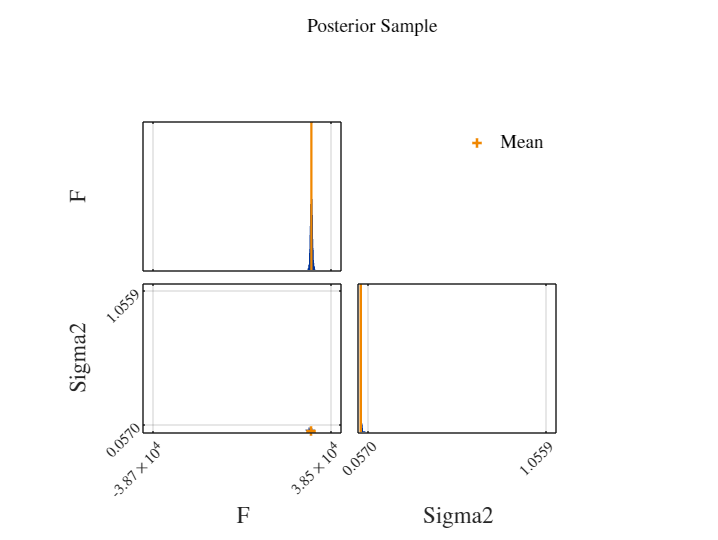

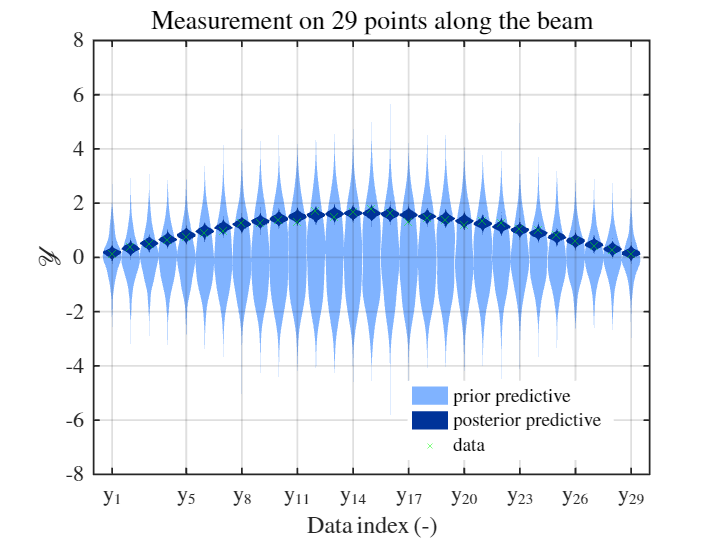

uq_postProcessInversion(BayesAnalysis,'priorPredictive',1000);
uq_display(BayesAnalysis);

## 11 -  90% error band on predictive posterior

### 90% confidence interval for E and $\delta$

set 90%  = 95%- 5%


uq_postProcessInversionMCMC(BayesAnalysis,'percentiles',[0.05,0.95]);

Obtained the lower bound and upper bound for E and $\delta$

F_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,1);
size(F_5_LowB)

ans =      1     1



F_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,1);
size(F_95_UpperB)

ans =      1     1





N_predict = 10

N_predict = 10


% sampling on E
F_90_sample_O = linspace(F_5_LowB,F_95_UpperB,N_predict)';
size(F_90_sample_O)

ans =     10     1



%Shuffle the order 
shuffledIndices = randperm(length(F_90_sample_O));
F_90_sample = F_90_sample_O(shuffledIndices);
size(F_90_sample)

ans =     10     1





%plot the sampling on F
figure
histogram(F_90_sample)

Predictive FE realization

Predict_sample = [F_90_sample];
size(Predict_sample)

ans =     10     1



%Loop to get the predictive FE deflection

YPCE_Predict = [];

for i = 1:N_predict
    
    Xval_Predict = Predict_sample(i,:);   

    Deflection = uq_evalModel(myPCE,Xval_Predict);
    YPCE_Predict = [YPCE_Predict;Deflection];


end

size(YPCE_Predict)

ans =     10    29


Spline curve fitting to smooth the line for the 90CI

x = 1:29;%29 measurement position along the beam

for i = 1:size(YPCE_Predict,1)
    
    P = polyfit(x,YPCE_Predict(i,:),3);
    xi = 1:0.1:29;
    YPCE_Predict_Poly(i,:) = polyval(P,xi);
end
size(YPCE_Predict_Poly)

ans =     10   281


Loop to fill the error band 90%CI

%loop to fill the error band
close all;

for i = 1:size(YPCE_Predict_Poly,1)-1
    hold on;
    fill([xi fliplr(xi)], [-YPCE_Predict_Poly(i,:) fliplr(-YPCE_Predict_Poly(i+1,:))], 'cyan', 'FaceAlpha', 1,'EdgeColor','none');
end

 hold on;
 
 xlabel('Beam length \it{L} \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Deflection (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
 ylim([-3.5 0])

scatter the measurement

x = 1:1:29;
size(x)

ans =      1    29



for i = 1: size(myData.y,1)
    scatter(x,-myData.y(i,:),'black','x');
    hold on;
end

draw the mean value of 90%CI

plot(xi,-mean(YPCE_Predict_Poly),'red','LineWidth',1.5);

legend

rectangle('Position', [22, -2.5,0.5, 0.25], 'FaceColor', 'cyan');
text(23, -2.35, '90% CI', 'FontSize', 8);
text(22.15, -2.7, 'x  measurement points', 'FontSize', 8);

line([22,22.6],[-3,-3],'linestyle','-','color','red','LineWidth',1.0);
text(23, -3, 'mean', 'FontSize', 8);

Plot the predictive individual lines

hold off;

% beam position

x_beam = 1:1:29

x_beam =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29



for i = 1:size(YPCE_Predict,1)
    
    plot(x_beam,-YPCE_Predict(i,:));
    hold on;
end
 xlabel('Beam length \it{L} \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Predictive deflection (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
  yticks('auto');
 ylim([-3.5 0])